clear all
clf
format shortg

g = 9.81;
v_0 = 180;

theta_A = 60;
theta_R = 20;


a)

syms t x
s_0 = 0;
v_0y = v_0 * sind(theta_A)

v_0y =        155.88



y_t = s_0 + t*v_0y + t^2 * (-g) / 2

$$y\_t = 90\,\sqrt{3}\,t-\frac{981\,t^{2}}{200}$$



v_t = diff(y_t, t)

$$v\_t = 90\,\sqrt{3}-\frac{981\,t}{100}$$


t_top = solve(v_t == 0, t);
vpa(t_top)

$$ans = 15.890374381365846729609599463357$$


vpa(subs(y_t, t_top), 5)

$$ans = 1238.5$$

Top højden bliver således $1238,5\ m$

b)

x_lin = linspace(0, 2000,1000)

x_lin =             0        2.002        4.004        6.006        8.008        10.01       12.012       14.014       16.016       18.018        20.02       22.022       24.024       26.026       28.028        30.03       32.032       34.034       36.036       38.038        40.04       42.042       44.044       46.046       48.048        50.05       52.052       54.054       56.056       58.058        60.06       62.062       64.064       66.066       68.068        70.07       72.072       74.074       76.076       78.078        80.08       82.082       84.084       86.086       88.088        90.09       92.092       94.094       96.096       98.098


v_0x = v_0 * cosd(theta_A)

v_0x =     90


x_t = s_0 + t*v_0x

$$x\_t = 90\,t$$


t_fun = solve(x == x_t, t)

$$t\_fun = \frac{x}{90}$$

% y_x = 

y_x = subs(y_t, t, t_fun)

$$y\_x = \sqrt{3}\,x-\frac{109\,x^{2}}{180000}$$


y_x_num = matlabFunction(y_x)

y_x_num = function_handle with value:
    @(x)sqrt(3.0).*x-x.^2.*6.055555555555556e-4



R_x = x * tand(theta_R)

$$R\_x = \frac{1639176211415221\,x}{4503599627370496}$$


R_x = @(x) x * tand(theta_R)

R_x = function_handle with value:
    @(x)x*tand(theta_R)



figure
fplot(y_x_num, [0,2500], 'DisplayName','Projektil')
hold on
fplot(R_x, [0,2500], 'DisplayName','Rampe')
hold off
yline(0, '--')
legend('Location','best')
grid('on')

vpa(y_x, 4)

$$ans = 1.732\,x-0.0006056\,x^{2}$$

vpa(R_x, 4)

$$ans = 0.364\,x$$

Vi får således forskrifterne


$$y_x = 1,732 x - 0,0006056*x^2$$



$$R_x = 0,364 * x$$


c) 


x_R_eq = y_x == R_x

$$x\_R\_eq = \sqrt{3}\,x-\frac{109\,x^{2}}{180000}=\frac{1639176211415221\,x}{4503599627370496}$$

vpa(x_R_eq)

$$ans = 1.7320508075688772935274463415059\,x-0.00060555555555555555555555555555556\,x^{2}=0.36397023426620234154427180328639\,x$$

x_R = solve(x_R_eq, x);
x_R = x_R(2);
vpa(x_R,4)

$$ans = 2259.0$$

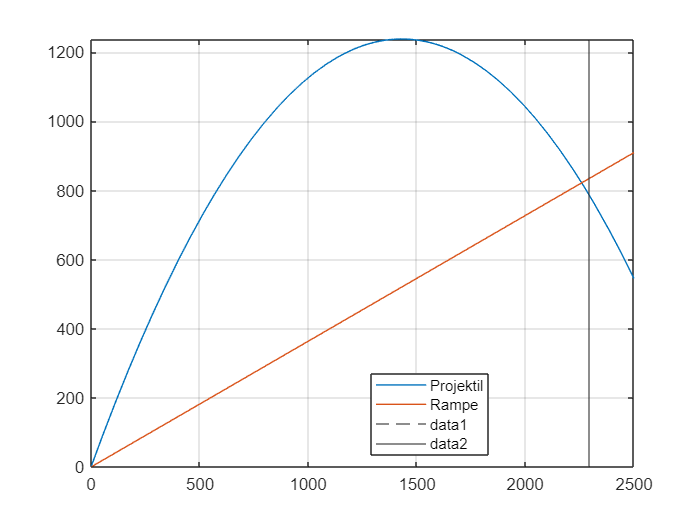


xline(2295)


R = x_R / cosd(theta_R);
vpa(R, 4)

$$ans = 2404.0$$

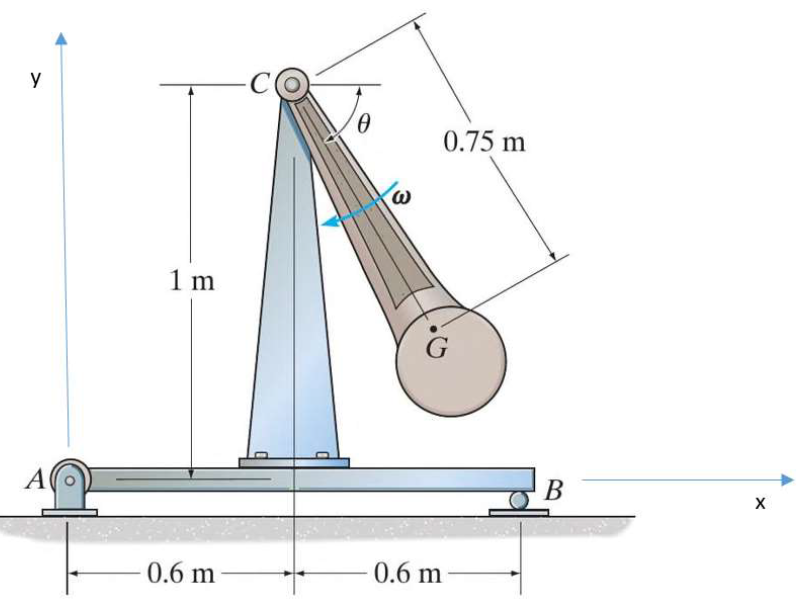

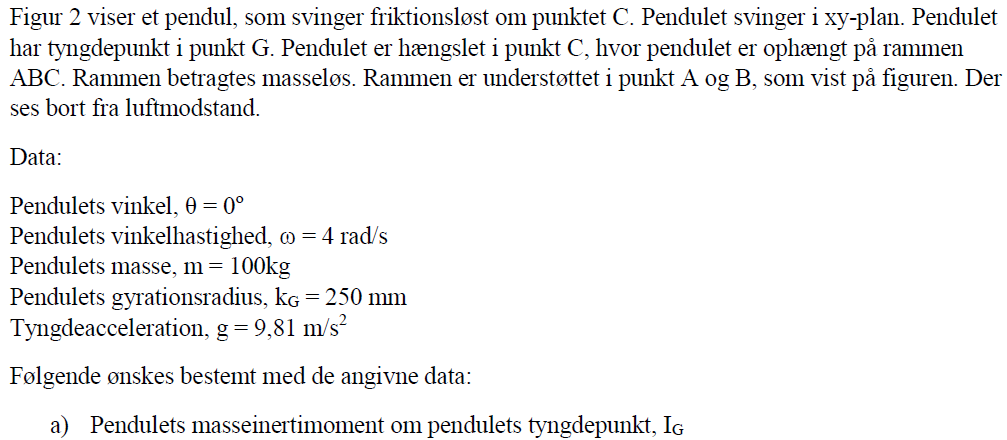

eta = 0;
eta_dot = 4;

m = 100; % kg
k_G = 0.250 %m

k_G = 0.2500

g = 9.81 %m / s^2

g = 9.8100


I_G = k_G^2 * m

I_G = 6.2500

Således fås masseinertimomentet til 6,25 kg/m^2

b) Pendulets masseinertimoment om pendulets hængslede ende, IC

d_CG = 0.75; %m
I_C = I_G + m * d_CG^2

I_C = 62.5000

Masseinertimomentet om hængled er således $62,5 kg/m^2

c) Frit legeme diagram for pendulet

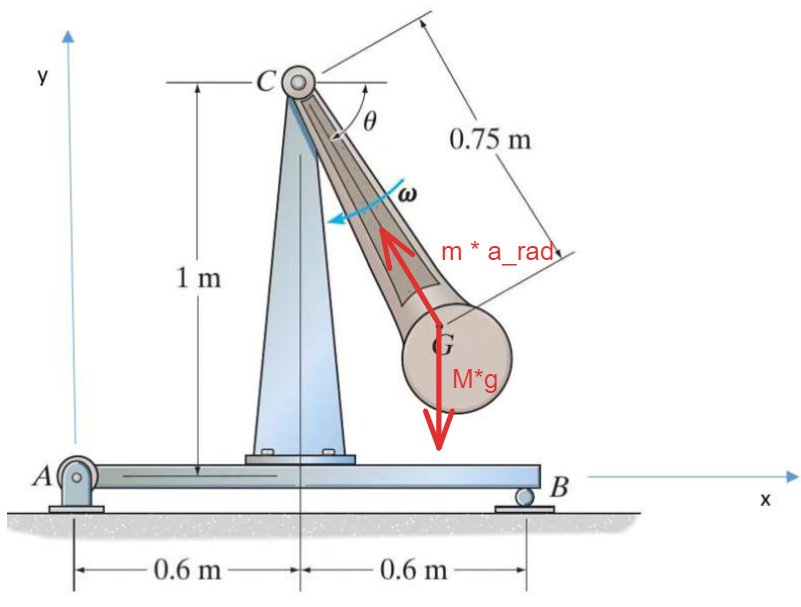

d) Kinetisk diagram for pendulet

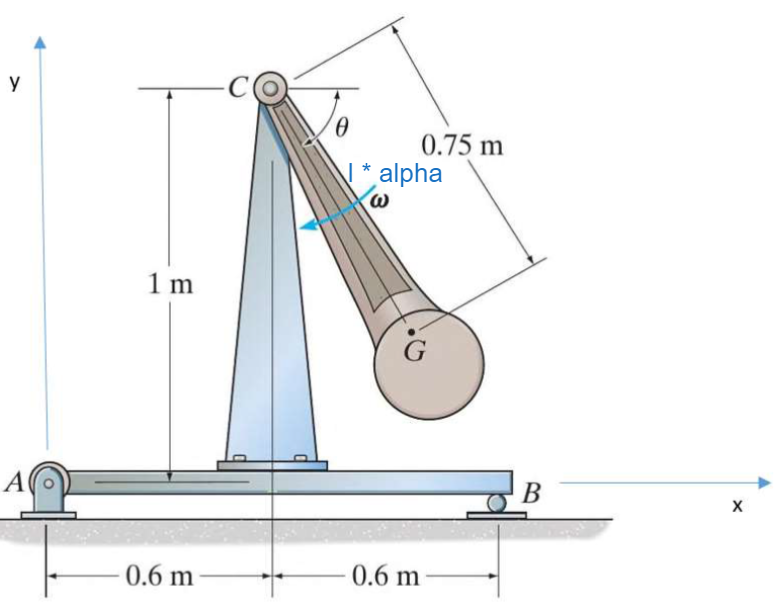

e) Pendulets vinkelacceleration, α

Der bruges moment ligning i stedet

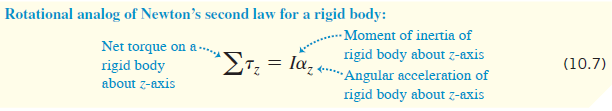

Da vinklen er 0 er den tangiale acceleration = g

tau = d_CG * g * m

tau = 735.7500

alpha = tau / I_C

alpha = 11.7720


% a_tan = g;
% alpha = a_tan / d_CG


f) Reaktionskræfterne Cx og Cy, i punkt C


$$a_t = r \cdot \alpha$$



$$a_n = r \cdot \omega^2$$



$$F=m*a$$



tau = d_CG * g * m

tau = 735.7500




C_x = - m * d_CG * eta_dot^2

C_x = -1200


C_y = m * a_tan - m * (d_CG * alpha)

C_y = 98.1000

g) Rammens reaktionskræfter i punkt A og B

Vi har de 3 ligevægtsligninger

Vi summer for momentet omkring A

C_x = abs(C_x)

C_x = 1200

C_y = abs(C_y)

C_y = 98.1000

syms B_y
A_M_eq = 0 == - C_x * 1 - C_y * 0.6 + B_y * 1.2;

B_y_sol = solve(A_M_eq, B_y);
vpa(B_y_sol)

$$ans = 1049.05$$


A_x = -C_x;
vpa(A_x)

$$ans = -1200.0$$

A_y = B_y_sol - C_y

$$A\_y = \frac{19019}{20}$$

vpa(A_y)

$$ans = 950.95$$

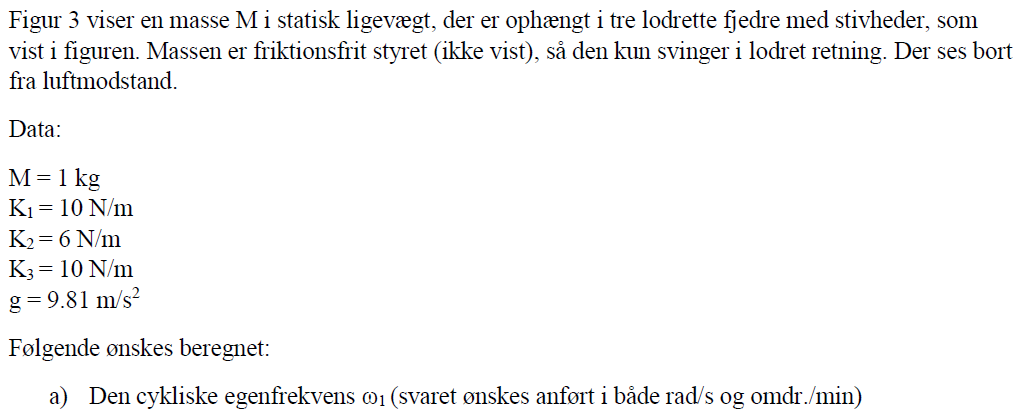

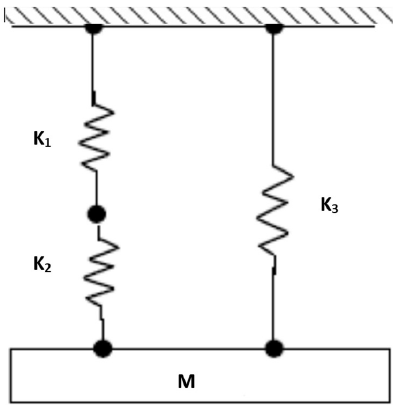

clear all
clf
m = 1 %kg

m = 1

K_1 = 10

K_1 = 10

K_2 = 6

K_2 = 6

K_3 = 10

K_3 = 10

g = 9.81

g = 9.8100

a) Den cykliske egenfrekvens ω1 (svaret ønskes anført i både rad/s og omdr./min)

To fjedre sidder i serie (K_1 + K_2)

disse to fjedre sidder paralelt med den sidste 


$$k_{tot} = \frac{1}{\frac{1}{K_serie} + \frac{1}{K_3}}$$


k = 1/(1/K_1 + 1/K_2) + K_3

k = 13.7500

w_n = sqrt(k/m) %egensvingningen

w_n = 3.7081

w_n_rpm = w_n * 60/(2*pi)

w_n_rpm = 35.4097

b)